# **4.1.1 ****if-elseif-else-end**`语句`

**if**`、`**elseif**`、`**else**`和`**end**`是`MATLAB`中的四个关键字，在第二章中我们强调过：不能定义与`MATLAB`关键字同名的变量。这四个关键字就构成了我们要学的第一种条件语句，后续我们将其简称为`**if**`语句``。`

`易错点：`**elseif**`关键字中间不能加空格，不能写成`**else if**`，这和`**C**`、`**Java**`等语言不同。`

`注意：在使用`if`语句时，`if`和`end`这两个关键字是无论如何都不能省略的。有很多新手在使用`MATLAB`时都会漏掉`end`这个关键字，导致后续无论输入什么命令`MATLAB`都没有反应，而`elseif`和`else`可以根据自己的需要来决定是否添加。`

`我们举一个具体的例子：计算分段函数`

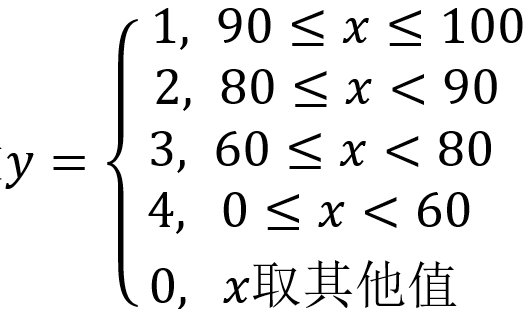

`你可以将这个分段函数想象成如下场景：给定一个同学的成绩（假设为整数），输出这个同学的等级。等级规则如下：`90`至`100`分为`1`级、`80`至`89`分为`2`级、`60`至`79`分为`3`级、低于`60`分为`4`级；如果成绩小于`0`分或者大于`100`分，则代表成绩输入有误，此时等级为`0`。`

x = 88;  % x表示成绩
if x>=90 && x <= 100
    dj = 1;  % 等级为1级
elseif x>=80 && x < 90
    dj = 2;  % 等级为2级
elseif x>=60 && x < 80
    dj = 3;  % 等级为3级
elseif x>=0 && x < 60
    dj = 4;  % 等级为4级
else
    dj = 0;  % 输入有误
end
dj

dj = 2

`另外，假设我们不考虑输入有误的情况，`x`全都取在`0`至`100`之间时：`

x = 68;  % x表示成绩
if x>=90 && x <= 100
    dj = 1;  % 等级为1级
elseif x>=80 && x < 90
    dj = 2;  % 等级为2级
elseif x>=60 && x < 80
    dj = 3;  % 等级为3级
else
    dj = 4;  % 等级为4级
end
dj

dj = 3

`我们可以对`if`和`elseif`后面的判断条件进行简化`

x = 68;  % x表示成绩
if x>=90
    dj = 1;  % 等级为1级
elseif x>=80
    dj = 2;  % 等级为2级
elseif x>=60
    dj = 3;  % 等级为3级
else
    dj = 4;  % 等级为4级
end
dj

dj = 3

前面我们说过，使用if语句时，if和end这两个关键字是无论如何都不能省略的，而elseif和else可以根据自己的编程需要来决定是否添加。

下面我们来举两个例子：

`（`1`）给定包含`2`个元素的行向量`a`，请使用`if`语句对向量`a`中的元素按照从小到大的顺序排序，并将排序后的向量保存为变量`sort_a`。例如`a = [5,3]`，那么`sort_a = [3,5]`。`

a = [5,3];
if a(1) > a(2)
    sort_a = [a(2),a(1)];
else
    sort_a = a;
end
sort_a

sort_a =      3     5


`当然，如果你非要用`elseif`，一定要在后面跟上条件，这时候可以省去`else`关键字，这样做的优点是让判断条件更加清楚，缺点是要多敲一点代码。`

a = [5,5];
if a(1) > a(2)
    sort_a = [a(2),a(1)];
elseif a(1) <= a(2)
    sort_a = a;
end
sort_a

sort_a =      5     5


`（`2`）给定一个包含`2`个元素的行向量`a`，请对向量`a`中的元素按照从小到大的顺序排序，将排序后的结果直接赋值到`a`上，不需要使用新的向量保存排序结果。`

a = [5,3];
if a(1) > a(2)
    a = [a(2),a(1)];
end
a

a =      3     5


`下面我们专门介绍一下`if`和`elseif`后面的表达式，在前面的例题中，表达式实际上就是判断条件，该判断条件通常是第三章学过的关系运算`(`例如`==`、`~=`、`>=)`和逻辑运算`(`例如`&`、`&&`、`||`、`|`、`~)`，因此运算结果要么是逻辑值`1(true)`，要么是逻辑值`0(false)`。例如`a(1)>a(2)`、`x>=80 && x<90`。事实上，`if`和`elseif`后面的表达式也支持其他运算，例如算术运算，其计算结果可以是一个数值，不一定非要是逻辑值`1`或者`0`。`

`为什么可以这样？第三章介绍逻辑运算时讲过：`MATLAB`会将非零数值视为逻辑`1`，将数值零视为逻辑`0`进行运算。例如：`3&5`返回逻辑`1`，`-4&0`返回逻辑`0`。``这里也是类似的：``如果`**if**`和`**elseif**`后面表达式的计算结果为非零数值，就会被当成`**true**`；如果计算结果为数值零，则会被当成`**false.**

`当然，我们在实际编程时很少用到这种情况，大家只需要了解背后的原理即可。`

if 3+5
    a = 10;
else
    a = 20;
end
a

a = 10

if 6-6
    a = 10;
else
    a = 20;
end
a

a = 20

if sin(2*pi)
    a = 10;
else
    a = 20;
end
a

a = 10

sin(2*pi)  % 浮点数计算的误差

ans = -2.4493e-16

**另外有同学可能在if或elseif后面放上了一个矩阵或者向量，这时候只有当这个矩阵或者向量中的所有元素都是非零元素时，才会被当成true。**

x = [1 2;0 3];
if x
    a = 10;
else
    a = 20;
end
a

a = 20


x = [1 2;-1 3];
if x
    a = 10;
else
    a = 20;
end
a

a = 10

思考题：修改上面的代码使得：当x中至少有一个元素为非零元素时，就会被当成true。

x = [1 2;0 3];
if any(x(:))
    a = 10;
else
    a = 20;
end
a

a = 10

x = [0 0;0 0];
if any(x(:))
    a = 10;
else
    a = 20;
end
a

a = 20

小技巧：利用智能缩进整理代码

选中代码后按快捷键“ctrl+i”

也可以选中代码后右键找到智能缩进：

无缩进：

x = 68;  % x表示成绩
if x>=90
    dj = 1;  % 等级为1级
elseif x>=80
    dj = 2;  % 等级为2级
elseif x>=60
    dj = 3;  % 等级为3级
else
    dj = 4;  % 等级为4级
end
dj

dj = 3

有缩进：

x = 68;  % x表示成绩
if x>=90
    dj = 1;  % 等级为1级
elseif x>=80
    dj = 2;  % 等级为2级
elseif x>=60
    dj = 3;  % 等级为3级
else
    dj = 4;  % 等级为4级
end
dj

dj = 3

`例题：已知a、b和c是三个互不相等的常数，请使用条件语句找出a、b和c三个数的最大值。（注意，这里是练习条件语句，请不要使用max函数直接求最大值）`

a = randi(1000,1,1)

a = 815

b = randi(1000,1,1)

b = 906

c = randi(1000,1,1)

c = 127

if a > b && a > c
    Max = a;  % 不要命名为小写的max，否则和内置函数重名了
elseif c > b && c > a
    Max = c;
else
    Max = b;
end
Max

Max = 906


Max == max([a b c])

ans = logical
   1

使用嵌套判断

if a>b
    if a>c   % 此时a>b且a>c
        Max=a;
    else  % 此时a>b且c>a
        Max=c;
    end  % a>c前面的那个if配套的end，通过缩进可以看出
else   % 此时a<b
    if b>c   % 此时a<b且b>c
        Max=b;
    else   % 此时a<b且b<c
        Max=c;
    end   % b>c前面的那个if配套的end，通过缩进可以看出
end  % 最上方的if配套的end
Max

Max = 906

Max == max([a b c])

ans = logical
   1

配套的讲解视频可在b站免费观看：

《MATLAB教程新手入门篇（数学建模清风主讲，适合零基础同学观看）》

[https://www.bilibili.com/video/BV1dN4y1Q7Kt/](https://www.bilibili.com/video/BV1dN4y1Q7Kt/)